clear
% #1264
syms x y
z=x^2-y^2

$$z = x^{2}-y^{2}$$

M=sym([1 1])

$$M = \left(\begin{array}{cc} 1 & 1 \end{array}\right)$$

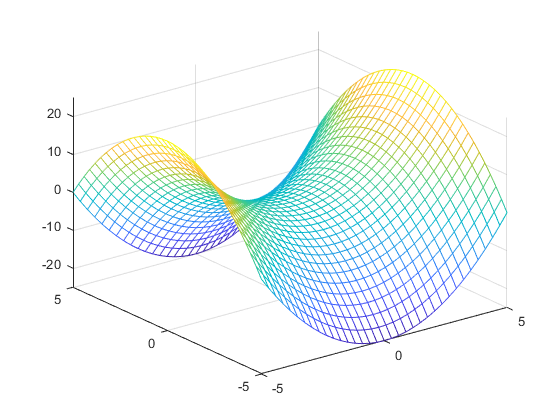

fmesh(z)


alfa=60*pi/180

alfa =    1.047197551196598


dzx=diff(z,x), dzy=diff(z,y)

$$dzx = 2\,x$$

$$dzy = -2\,y$$


dzxM=subs(dzx,[x y],M), dzyM=subs(dzy,[x y],M)

$$dzxM = 2$$

$$dzyM = -2$$


dzl=dzxM*cos(alfa)+dzyM*sin(alfa)

$$dzl = 1-\sqrt{3}$$

vpa(dzl)

$$ans = -0.73205$$

digits(4)

gdz=gradient(z)

$$gdz = \left(\begin{array}{c} 2\,x\\ -2\,y \end{array}\right)$$

gdzM=subs(gdz,[x y],M)

$$gdzM = \left(\begin{array}{c} 2\\ -2 \end{array}\right)$$

dzl2=gdzM(1)*cos(alfa)+gdzM(2)*sin(alfa)

$$dzl2 = 1-\sqrt{3}$$

% #1265
% 1)
syms x y z;
u=x*y^2*z^3

$$u = x\,y^{2}\,z^{3}$$

M=sym([3 2 1]);
N=sym([5 4 2]);
digits(5)

MN=N-M

$$MN = \left(\begin{array}{ccc} 2 & 2 & 1 \end{array}\right)$$

cos_alfa=MN(1)/length(MN)

$$cos\_alfa = \frac{2}{3}$$

cos_beta=MN(2)/length(MN)

$$cos\_beta = \frac{2}{3}$$

cos_gamma=MN(3)/length(MN)

$$cos\_gamma = \frac{1}{3}$$


dux=diff(u,x), duy=diff(u,y), duz=diff(u,z)

$$dux = y^{2}\,z^{3}$$

$$duy = 2\,x\,y\,z^{3}$$

$$duz = 3\,x\,y^{2}\,z^{2}$$


duxM=subs(dux,[x y z],M)

$$duxM = 4$$

duyM=subs(duy,[x y z],M)

$$duyM = 12$$

duzM=subs(duz,[x y z],M)

$$duzM = 36$$


dul=duxM*cos_alfa+duyM*cos_beta+duzM*cos_gamma

$$dul = \frac{68}{3}$$

vpa(dul)

$$ans = 22.667$$

% 2)
Cos_A=MN/length(MN)

$$Cos\_A = \left(\begin{array}{ccc} \frac{2}{3} & \frac{2}{3} & \frac{1}{3} \end{array}\right)$$

gdu=gradient(u)

$$gdu = \left(\begin{array}{c} y^{2}\,z^{3}\\ 2\,x\,y\,z^{3}\\ 3\,x\,y^{2}\,z^{2} \end{array}\right)$$

gduM=subs(gdu,[x y z],M)

$$gduM = \left(\begin{array}{c} 4\\ 12\\ 36 \end{array}\right)$$

dul2=dot(gduM,Cos_A)

$$dul2 = \frac{68}{3}$$

% #1266
% 1)
syms x y;
z=log(x^2+y^2)

$$z = \log\left(x^{2}+y^{2}\right)$$

M=[3 4]

M =      3     4


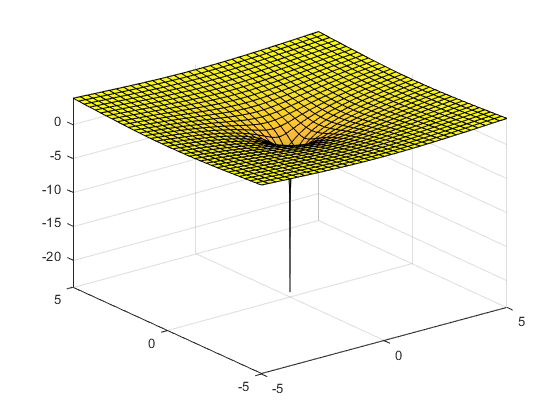

fsurf(z)

dzx=diff(z,x), dzy=diff(z,y)

$$dzx = \frac{2\,x}{x^{2}+y^{2}}$$

$$dzy = \frac{2\,y}{x^{2}+y^{2}}$$

dzxM=subs(dzx,[x y],M), dzyM=subs(dzy,[x y],M)

$$dzxM = \frac{6}{25}$$

$$dzyM = \frac{8}{25}$$

gdz=[dzxM dzyM]

$$gdz = \left(\begin{array}{cc} \frac{6}{25} & \frac{8}{25} \end{array}\right)$$

dzl1=sqrt(sum(gdz.*gdz))

$$dzl1 = \frac{2}{5}$$

% 2)
gdz2=gradient(z)

$$gdz2 = \left(\begin{array}{c} \frac{2\,x}{x^{2}+y^{2}}\\ \frac{2\,y}{x^{2}+y^{2}} \end{array}\right)$$

gdz2M=subs(gdz2,[x y],M)

$$gdz2M = \left(\begin{array}{c} \frac{6}{25}\\ \frac{8}{25} \end{array}\right)$$

% #1267
syms x y z;
u=tan(x)-x+3*sin(y)-sin(y)^3+z+cot(z);
M=sym([pi/4 pi/3 pi/2])

$$M = \left(\begin{array}{ccc} \frac{\pi }{4} & \frac{\pi }{3} & \frac{\pi }{2} \end{array}\right)$$

dux=diff(u,x), duy=diff(u,y), duz=diff(u,z)

$$dux = {\tan\left(x\right)}^{2}$$

$$duy = 3\,\cos\left(y\right)-3\,\cos\left(y\right)\,{\sin\left(y\right)}^{2}$$

$$duz = -{\cot\left(z\right)}^{2}$$


Gdu=[diff(u,x);diff(u,y);diff(u,z)]

$$Gdu = \left(\begin{array}{c} {\tan\left(x\right)}^{2}\\ 3\,\cos\left(y\right)-3\,\cos\left(y\right)\,{\sin\left(y\right)}^{2}\\ -{\cot\left(z\right)}^{2} \end{array}\right)$$


GduM=subs(Gdu,[x,y,z],M)

$$GduM = \left(\begin{array}{c} 1\\ \frac{3}{8}\\ 0 \end{array}\right)$$

lgm=sqrt(sum(GduM.*GduM))

$$lgm = \frac{\sqrt{73}}{8}$$

Cos_A=simplify(GduM/lgm)

$$Cos\_A = \left(\begin{array}{c} \frac{8\,\sqrt{73}}{73}\\ \frac{3\,\sqrt{73}}{73}\\ 0 \end{array}\right)$$


Gdu2=gradient(u)

$$Gdu2 = \left(\begin{array}{c} {\tan\left(x\right)}^{2}\\ 3\,\cos\left(y\right)-3\,\cos\left(y\right)\,{\sin\left(y\right)}^{2}\\ -{\cot\left(z\right)}^{2} \end{array}\right)$$

Gdu2M=subs(Gdu2,[x y z], M)

$$Gdu2M = \left(\begin{array}{c} 1\\ \frac{3}{8}\\ 0 \end{array}\right)$$

% #1268
syms x y;
z=x^2-x*y+y^2;
M=sym([1 1])

$$M = \left(\begin{array}{cc} 1 & 1 \end{array}\right)$$

L=sym([6 8])

$$L = \left(\begin{array}{cc} 6 & 8 \end{array}\right)$$

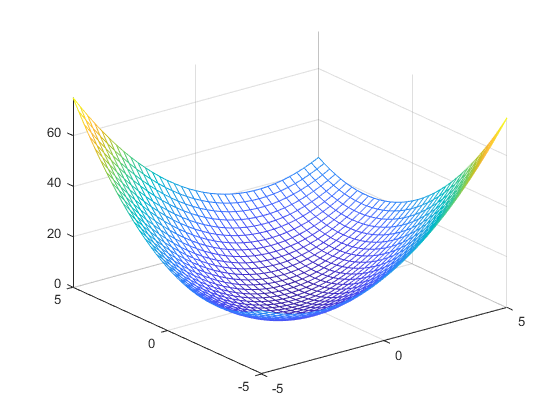

fmesh(z)


LL=sqrt(sum(L.*L))

$$LL = 10$$

cos_a=L(1)/LL, sin_a=L(2)/LL

$$cos\_a = \frac{3}{5}$$

$$sin\_a = \frac{4}{5}$$


Gdz=[diff(z,x);diff(z,y)]

$$Gdz = \left(\begin{array}{c} 2\,x-y\\ 2\,y-x \end{array}\right)$$

GdzM=subs(Gdz,[x y],M)

$$GdzM = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$


GdzL=GdzM(1)*cos_a+GdzM(2)*sin_a

$$GdzL = \frac{7}{5}$$


Gdz2=gradient(z)

$$Gdz2 = \left(\begin{array}{c} 2\,x-y\\ 2\,y-x \end{array}\right)$$

Gdz2M=subs(Gdz2,[x y],M)

$$Gdz2M = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

% #1269
clear
syms x y z;
u=asin(z/sqrt(x^2+y^2))

$$u = \mathrm{asin}\left(\frac{z}{\sqrt{x^{2}+y^{2}}}\right)$$

M=sym([1 1 1]);
N=sym([3 2 3]);
digits(5)

MN=N-M

$$MN = \left(\begin{array}{ccc} 2 & 1 & 2 \end{array}\right)$$

lenMN=sqrt(sum(MN.*MN))

$$lenMN = 3$$

Cos_A=MN/lenMN

$$Cos\_A = \left(\begin{array}{ccc} \frac{2}{3} & \frac{1}{3} & \frac{2}{3} \end{array}\right)$$


gdu=[simplify(diff(u,x));simplify(diff(u,y));simplify(diff(u,z))]

$$gdu = \left(\begin{array}{c} -\frac{x\,z}{\left(x^{2}+y^{2}\right)\,\sqrt{x^{2}+y^{2}-z^{2}}}\\ -\frac{y\,z}{\left(x^{2}+y^{2}\right)\,\sqrt{x^{2}+y^{2}-z^{2}}}\\ \frac{1}{\sqrt{x^{2}+y^{2}-z^{2}}} \end{array}\right)$$

gduM=subs(gdu,[x y z],M)

$$gduM = \left(\begin{array}{c} -\frac{1}{2}\\ -\frac{1}{2}\\ 1 \end{array}\right)$$

dul=dot(gduM,Cos_A)

$$dul = \frac{1}{6}$$

vpa(dul)

$$ans = 0.16667$$


gdu=simplify(gradient(u))

$$gdu = \left(\begin{array}{c} -\frac{x\,z}{\left(x^{2}+y^{2}\right)\,\sqrt{x^{2}+y^{2}-z^{2}}}\\ -\frac{y\,z}{\left(x^{2}+y^{2}\right)\,\sqrt{x^{2}+y^{2}-z^{2}}}\\ \frac{1}{\sqrt{x^{2}+y^{2}-z^{2}}} \end{array}\right)$$

gduM=subs(gdu,[x y z],M)

$$gduM = \left(\begin{array}{c} -\frac{1}{2}\\ -\frac{1}{2}\\ 1 \end{array}\right)$$

dul2=dot(gduM,Cos_A)

$$dul2 = \frac{1}{6}$$

% #1270
clear
% 1)
syms x y z;
u=log(x^2+y^2+z^2)

$$u = \log\left(x^{2}+y^{2}+z^{2}\right)$$

M=sym([1 2 1]);
r=sym([2 4 4]);
digits(5)

lenr=sqrt(sum(r.*r))

$$lenr = 6$$

cos_alfa=r(1)/lenr

$$cos\_alfa = \frac{1}{3}$$

cos_beta=r(2)/lenr

$$cos\_beta = \frac{2}{3}$$

cos_gamma=r(3)/lenr

$$cos\_gamma = \frac{2}{3}$$


gdu=[simplify(diff(u,x));simplify(diff(u,y));simplify(diff(u,z))]

$$gdu = \left(\begin{array}{c} \frac{2\,x}{x^{2}+y^{2}+z^{2}}\\ \frac{2\,y}{x^{2}+y^{2}+z^{2}}\\ \frac{2\,z}{x^{2}+y^{2}+z^{2}} \end{array}\right)$$

gduM=subs(gdu,[x y z],M)

$$gduM = \left(\begin{array}{c} \frac{1}{3}\\ \frac{2}{3}\\ \frac{1}{3} \end{array}\right)$$

dul=gduM(1)*cos_alfa+gduM(2)*cos_beta+gduM(3)*cos_gamma

$$dul = \frac{7}{9}$$

vpa(dul)

$$ans = 0.77778$$


% 2)
Cos_A=r/lenr

$$Cos\_A = \left(\begin{array}{ccc} \frac{1}{3} & \frac{2}{3} & \frac{2}{3} \end{array}\right)$$

gdu=gradient(u)

$$gdu = \left(\begin{array}{c} \frac{2\,x}{x^{2}+y^{2}+z^{2}}\\ \frac{2\,y}{x^{2}+y^{2}+z^{2}}\\ \frac{2\,z}{x^{2}+y^{2}+z^{2}} \end{array}\right)$$

gduM=subs(gdu,[x y z],M)

$$gduM = \left(\begin{array}{c} \frac{1}{3}\\ \frac{2}{3}\\ \frac{1}{3} \end{array}\right)$$

dul2=dot(gduM,Cos_A)

$$dul2 = \frac{7}{9}$$

% #1271
syms x y z x0 y0 z0 real;
r=sqrt(x^2+y^2+z^2)

$$r = \sqrt{x^{2}+y^{2}+z^{2}}$$

u=1/r

$$u = \frac{1}{\sqrt{x^{2}+y^{2}+z^{2}}}$$

M=[x0 y0 z0]

$$M = \left(\begin{array}{ccc} x_{0} & y_{0} & z_{0} \end{array}\right)$$


gdu=[simplify(diff(u,x));simplify(diff(u,y));simplify(diff(u,z))]

$$gdu = \left(\begin{array}{c} -\frac{x}{{\left(x^{2}+y^{2}+z^{2}\right)}^{3/2}}\\ -\frac{y}{{\left(x^{2}+y^{2}+z^{2}\right)}^{3/2}}\\ -\frac{z}{{\left(x^{2}+y^{2}+z^{2}\right)}^{3/2}} \end{array}\right)$$

gduM=subs(gdu,[x y z],M)

$$gduM = \left(\begin{array}{c} -\frac{x_{0}}{{\left({x_{0}}^{2}+{y_{0}}^{2}+{z_{0}}^{2}\right)}^{3/2}}\\ -\frac{y_{0}}{{\left({x_{0}}^{2}+{y_{0}}^{2}+{z_{0}}^{2}\right)}^{3/2}}\\ -\frac{z_{0}}{{\left({x_{0}}^{2}+{y_{0}}^{2}+{z_{0}}^{2}\right)}^{3/2}} \end{array}\right)$$


gdul=simplify(sqrt(sum(gduM.*gduM)))

$$gdul = \frac{1}{{x_{0}}^{2}+{y_{0}}^{2}+{z_{0}}^{2}}$$

cos_gduv=simplify(gduM/gdul)

$$cos\_gduv = \left(\begin{array}{c} -\frac{x_{0}}{\sqrt{{x_{0}}^{2}+{y_{0}}^{2}+{z_{0}}^{2}}}\\ -\frac{y_{0}}{\sqrt{{x_{0}}^{2}+{y_{0}}^{2}+{z_{0}}^{2}}}\\ -\frac{z_{0}}{\sqrt{{x_{0}}^{2}+{y_{0}}^{2}+{z_{0}}^{2}}} \end{array}\right)$$

% #1272
syms x y z;
u=x*y*z;
M=sym([2 1 1])

$$M = \left(\begin{array}{ccc} 2 & 1 & 1 \end{array}\right)$$

gdu=[simplify(diff(u,x));simplify(diff(u,y));simplify(diff(u,z))]

$$gdu = \left(\begin{array}{c} y\,z\\ x\,z\\ x\,y \end{array}\right)$$

gduM=subs(gdu,[x y z],M)

$$gduM = \left(\begin{array}{c} 1\\ 2\\ 2 \end{array}\right)$$

gdul=simplify(sqrt(sum(gduM.*gduM)))

$$gdul = 3$$

cos_gduv=simplify(gduM/gdul)

$$cos\_gduv = \left(\begin{array}{c} \frac{1}{3}\\ \frac{2}{3}\\ \frac{2}{3} \end{array}\right)$$

% #1273
% 1)
syms x y z;
u=x/2+y/3+z/6

$$u = \frac{x}{2}+\frac{y}{3}+\frac{z}{6}$$

l=sym([6 3 -6])

$$l = \left(\begin{array}{ccc} 6 & 3 & -6 \end{array}\right)$$

lenl=sqrt(sum(l.*l))

$$lenl = 9$$

Cos_A=l/lenl

$$Cos\_A = \left(\begin{array}{ccc} \frac{2}{3} & \frac{1}{3} & -\frac{2}{3} \end{array}\right)$$

gdu=[simplify(diff(u,x));simplify(diff(u,y));simplify(diff(u,z))]

$$gdu = \left(\begin{array}{c} \frac{1}{2}\\ \frac{1}{3}\\ \frac{1}{6} \end{array}\right)$$

dul=dot(gdu,Cos_A)

$$dul = \frac{1}{3}$$

vpa(dul)

$$ans = 0.33333$$


% 2)
gdu=gradient(u)

$$gdu = \left(\begin{array}{c} \frac{1}{2}\\ \frac{1}{3}\\ \frac{1}{6} \end{array}\right)$$

dul2=dot(gdu,Cos_A)

$$dul2 = \frac{1}{3}$$